close all
clear
clc

syms x y z t r phi z real
syms e n beta mu_0 c omega real positive
syms pi

% Magnetic vector potential (without limit of Bessel function)
Az=(-e)*mu_0/(2*pi)^2*...
   besselk(0,1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
   exp(-1i*omega/(beta*c)*z);

% % Magnetic vector potential (with limit of Bessel function)
% Az=(-e)*mu_0/(2*pi)^2*...
%    sqrt(pi/(2*omega/c*sqrt(n^2-beta^(-2))*r))*exp(-1i*pi/4)*exp(-1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
%    exp(-1i*omega/(beta*c)*z);

% Derive electric field from the potentials
Er=simplify(-c/(n^2*beta)*diff(Az,r))

$$Er = -\frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\omega \,z\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta^{2}\,n^{2}\,\pi^{2}}$$

Ez=simplify(-1i*omega*Az-c/(n^2*beta)*diff(Az,z))

$$Ez = \frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\omega \,z\,\mathrm{i}}{\beta \,c}}\,\left(\beta^{2}\,n^{2}\,\mathrm{i}-\mathrm{i}\right)\,K_{0}\left(\frac{\omega \,r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)}{4\,\beta^{2}\,n^{2}\,\pi^{2}}$$

% Derive magnetic field from the potentials
Bpconj=simplify(-diff(conj(Az),r));
Hp=simplify(1/mu_0*conj(Bpconj))

$$Hp = -\frac{e\,\omega \,{\mathrm{e}}^{-\frac{\omega \,z\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,r\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta \,c\,\pi^{2}}$$

% Assume r>0 to simplify the expressions
assume(r,'positive')

% Impose analytical solution
H=[0
   subs(Hp,[r,z],[sqrt(y^2+z^2),x])*(-sin(atan2(z,y)))
   subs(Hp,[r,z],[sqrt(y^2+z^2),x])*(+cos(atan2(z,y)))]

$$H = \left[\begin{array}{c} 0\\ \frac{e\,\omega \,z\,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,\sqrt{y^{2}+z^{2}}\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta \,c\,\pi^{2}\,\sqrt{y^{2}+z^{2}}}\\ -\frac{e\,\omega \,y\,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,\sqrt{y^{2}+z^{2}}\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta \,c\,\pi^{2}\,\sqrt{y^{2}+z^{2}}} \end{array}\right]$$

E=[subs(Ez,[r,z],[sqrt(y^2+z^2),x])
   subs(Er,[r,z],[sqrt(y^2+z^2),x])*(+cos(atan2(z,y)))
   subs(Er,[r,z],[sqrt(y^2+z^2),x])*(+sin(atan2(z,y)))]

$$E = \left[\begin{array}{c} \frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\left(\beta^{2}\,n^{2}\,\mathrm{i}-\mathrm{i}\right)\,K_{0}\left(\frac{\omega \,\sqrt{y^{2}+z^{2}}\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)}{4\,\beta^{2}\,n^{2}\,\pi^{2}}\\ -\frac{e\,\mu_{0}\,\omega \,y\,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,\sqrt{y^{2}+z^{2}}\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta^{2}\,n^{2}\,\pi^{2}\,\sqrt{y^{2}+z^{2}}}\\ -\frac{e\,\mu_{0}\,\omega \,z\,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\sqrt{\beta^{2}\,n^{2}-1}\,K_{1}\left(\frac{\omega \,\sqrt{y^{2}+z^{2}}\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\mathrm{i}}{4\,\beta^{2}\,n^{2}\,\pi^{2}\,\sqrt{y^{2}+z^{2}}} \end{array}\right]$$

j=[0
   0
   0]

j =      0
     0
     0


% Additional variables to compute residuals
X=[x,y,z];
epsilon_0=1/(c^2*mu_0);
mu=mu_0;
epsilon=n^2*epsilon_0;
assume(beta^2*n^2>1)
 
% Check residual of magnetic field
R_H=simplify(...
    1i*mu*omega*H...
    +mycurl(E,X))

$$R\_H = \left[\begin{array}{c} 0\\ 0\\ 0 \end{array}\right]$$

% Check residual of electric field
% CONSIDER THAT Y/SIGN(Y)=ABS(Y) (OR Y*SIGN(Y)=ABS(Y))
R_E=simplify(...
    1i*epsilon*omega*E...
    -mycurl(H,X)...
    +j)

$$R\_E = \left[\begin{array}{c} 0\\ 0\\ 0 \end{array}\right]$$

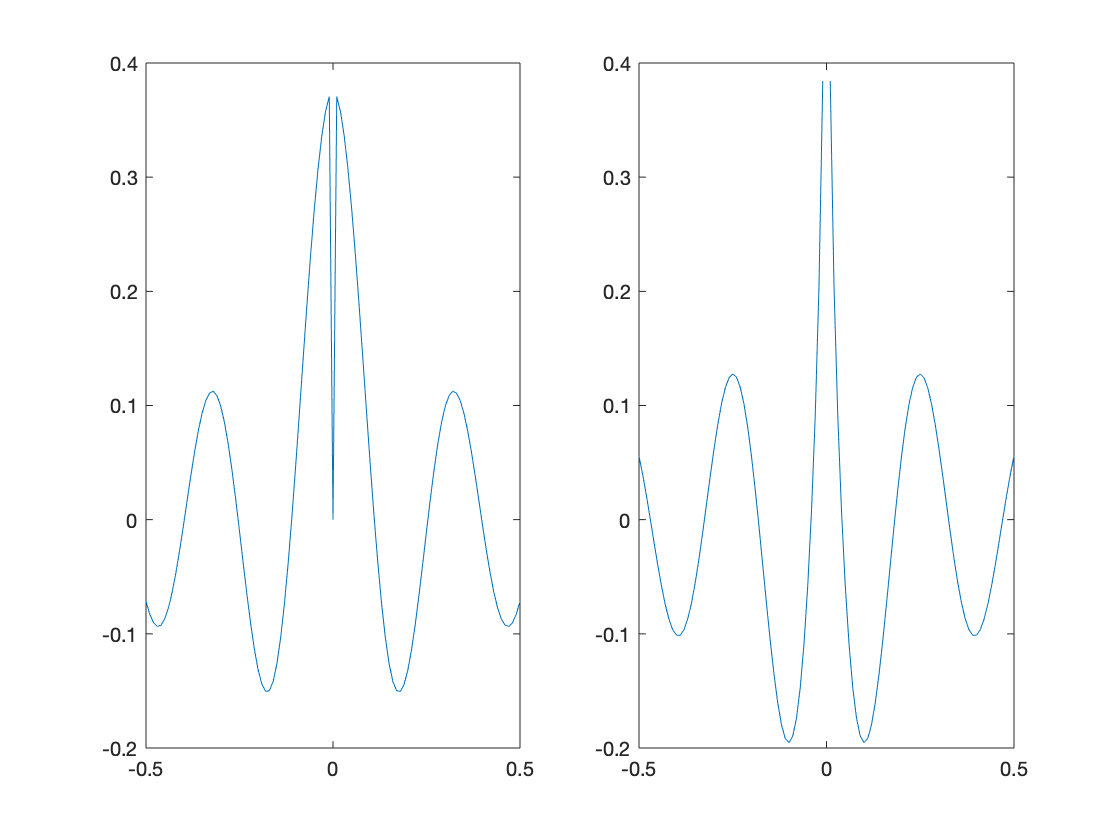

% Plot solution
omega=2*pi*2; mu_0=1; e=1; beta=1; c=1; n=2; pi=3.141592653589793;
x=0; y=linspace(-1/2,+1/2,101); z=0;
figure
subplot(1,2,1)
plot(y,real(eval(E(1))))
subplot(1,2,2)
plot(y,imag(eval(E(1))))

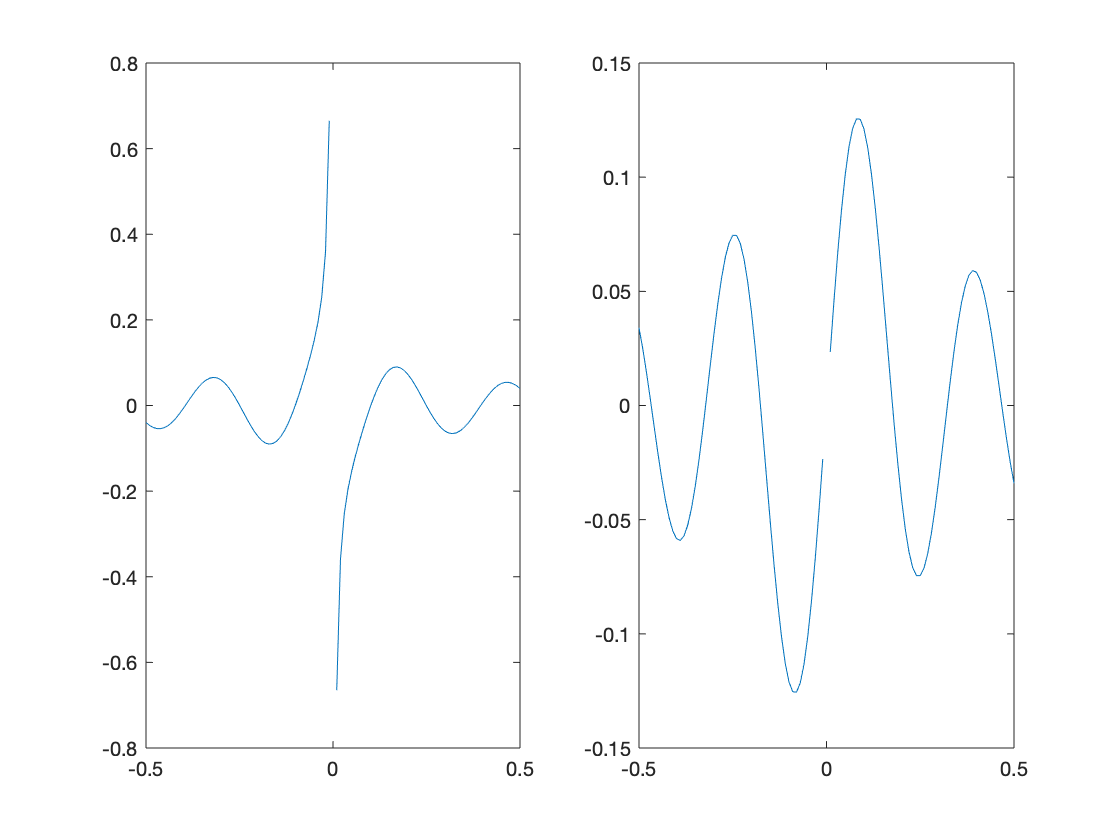

figure
subplot(1,2,1)
plot(y,real(eval(E(2))))
subplot(1,2,2)
plot(y,imag(eval(E(2))))
figure

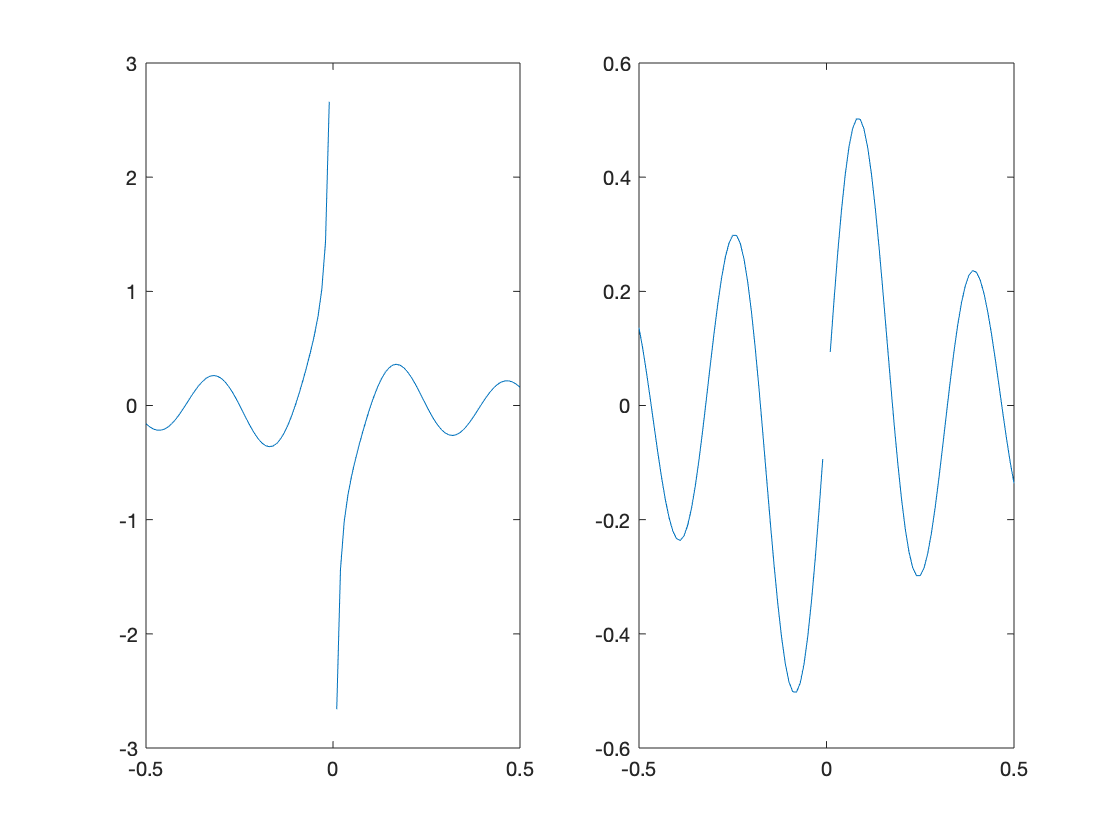

subplot(1,2,1)
plot(y,real(eval(H(3))))
subplot(1,2,2)
plot(y,imag(eval(H(3))))
